# Symbolic calculation of the Jacobian matrix of the manipulator ABB IRB120.

## **Part 1: Obtain the Geometric Jacobian of the IRB120 manipulator**

### Direct** Kinematic Model (DKM)**

Firstly, the direct kinematic model of the ABB IRB120 manipulator must be defined. These are the frames assigned to every joint of the manipulator following the Denavit-Hartemberg standard method (DH1):

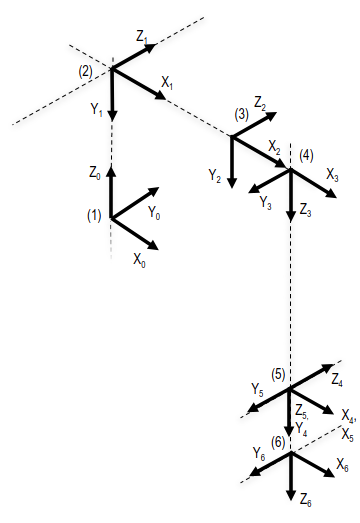

And the following table of Denavit-Hartenberg parameters:

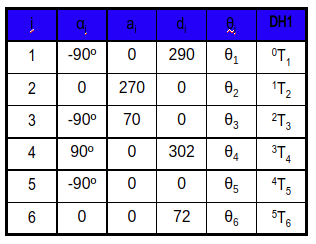

**Note.-** The references for angles in this Direct Kinematic Model (DKM) do not correspond to the IRB120 manufacturer reference frame.

### **Solution.-**

The first step is to declare the symbolic variables: joint variables and Denavit-Hartenberg parameters. We can also create two vectors with the sine and cosine of the articular variables, to simplify matrices construction.

The first step is to compute the homogeneus transform matrices for each pair of jonts along the manipulator, for DH1:

We need matrices form reference from {0] to {6}. Using symbolic computation (using functions available in Virtual Campus):

syms alpha a theta d real
T=despZ(d)*rotZ(theta)*despX(a)*rotX(alpha)

$$T = \left(\begin{array}{cccc} \cos\left(\theta \right) & -\cos\left(\alpha \right)\,\sin\left(\theta \right) & \sin\left(\alpha \right)\,\sin\left(\theta \right) & a\,\cos\left(\theta \right)\\ \sin\left(\theta \right) & \cos\left(\alpha \right)\,\cos\left(\theta \right) & -\sin\left(\alpha \right)\,\cos\left(\theta \right) & a\,\sin\left(\theta \right)\\ 0 & \sin\left(\alpha \right) & \cos\left(\alpha \right) & d\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Each matrix can be evaluated for each row in the DH1 parameters table:

% Standard Denavit-Hartemberg parameters (DH1)
di=[0.290 0 0 0.302 0 0.072];
ai=[0 0.270 0.070 0 0 0];
alphai=[-pi/2 0 -pi/2 pi/2 -pi/2 0];
syms q1 q2 q3 q4 q5 q6 real
qi=[q1 q2 q3 q4 q5 q6];

T01=subs(T,{a,alpha,d,theta},{ai(1),alphai(1),di(1),qi(1)});
T12=subs(T,{a,alpha,d,theta},{ai(2),alphai(2),di(2),qi(2)});
T23=subs(T,{a,alpha,d,theta},{ai(3),alphai(3),di(3),qi(3)});
T34=subs(T,{a,alpha,d,theta},{ai(4),alphai(4),di(4),qi(4)});
T45=subs(T,{a,alpha,d,theta},{ai(5),alphai(5),di(5),qi(5)});
T56=subs(T,{a,alpha,d,theta},{ai(6),alphai(6),di(6),qi(6)});


Then, the matrix from {0} to {6} of the DKM can be computed (and the rest of matrices to every joint from frame {0}):

%T01 computed before.
T02=simplify(T01*T12);
T03=simplify(T02*T23);
T04=simplify(T03*T34);
T05=simplify(T04*T45);
T06=simplify(T05*T56);

### Jacobian matrix

Compute the Jacobian matrix of the IRB120 manipulator referenced to the base frame using the geometric method.

In order to build the Jacobian matrix we need the vectors z_i (the z vectors of the reference frames), and the vectors p_i (the position vectors of the origins of the reference frames). Attention, must be referenced to the system {0}. We have to use the matrices that we have found in the previous step, in the DKM. For z_i vectors we use the corresponding rotation matrix and p_i vectors are the position part of the homogeneus transformations matrices (position vectors of the origin of the corresponding frames).

%joint vectors (zi)
zL=[0 0 1]';
z0=zL;
%%%%% PUT YOUR CODE HERE %%%%%%
% Complete from z1 to z5
z1=T01(1:3,1:3)*z0;
z2=T02(1:3,1:3)*z0;
z3=T03(1:3,1:3)*z0;
z4=T04(1:3,1:3)*z0;
z5=T05(1:3,1:3)*z0;

%position vectors (pi); they are the position part of the homogeneus
%transformation matrices (position of the origin of the reference frame)
p0=[0 0 0]';
%%%%% PUT YOUR CODE HERE %%%%%%
% Complete from p1 to p6
p1=T01(1:3,4);
p2=T02(1:3,4);
p3=T03(1:3,4);
p4=T04(1:3,4);
p5=T05(1:3,4);
p6=T06(1:3,4);

The last step is to build the Jacobian matrix, which in this case (all joint are revolute) corresponds to:


$$J(q)=\left[ {\begin{array}{cccc} z_0 \times (p_6-p_0) & z_1 \times (p_6-p_1) & z_2 \times (p_6-p_2) & z_3 \times (p_6-p_3) & z_4 \times (p_6-p_4) & z_5 \times (p_6-p_5) \\ z_0 & z_1 & z_2 & z_3 & z_4 & z_5 \end{array} } \right]$$


We can compute the matrix by columns (J1, J2, J3, J4, J5 and J6), where each column is composed by the definition. E.g., J1 would be:

J1=[cross(z0,(p6(1:3)-p0(1:3)));z0];

%Columns according to the algorithm (J=[JP;JO]); the left side with the three
%first elements of each pi vector and the right side with the z_i vector
J1=simplify([cross(z0,(p6-p0));z0]);
J2=simplify([cross(z1,(p6-p1));z1]);
J3=simplify([cross(z2,(p6-p2));z2]);
J4=simplify([cross(z3,(p6-p3));z3]);
J5=simplify([cross(z4,(p6-p4));z4]);
J6=simplify([cross(z5,(p6-p5));z5]);

Finally, the Jacobian matrix is built. A reduced Jacobian matrix can also be defined, in which we eliminate the null rows or columns, which do not contribute to the transition from joint velocities to Cartesian velocities.

JPO=simplify([J1 J2 J3 J4 J5 J6])

## Part 2: Compute the Cartesian velocities of the end-effector

Given a robot configuration:

q=[pi/2 pi/4 -pi/4 pi/6 pi/2 pi/6]';

and the joint velocities:

qv=[0.5 0.1 0.4 0.7 0.1 0.5]';

Firstly, the Jacobian matrix must be evaluated in the robot configuration:

Jq=subs(JPO,{q1,q2,q3,q4,q5,q6},{q(1),q(2),q(3),q(4),q(5),q(6)})

$$Jq = \begin{array}{l} \left(\begin{array}{cccccc} \sigma_{1} & 0 & 0 & -\sigma_{2} & 0 & 0\\ -\frac{9}{250} & -\sigma_{3}-\frac{151}{500} & -\frac{151}{500} & \frac{9}{250} & 0 & 0\\ 0 & \sigma_{1} & \sigma_{2}-\frac{7}{100} & 0 & \frac{9}{125} & 0\\ 0 & -1 & -1 & 0 & -\frac{\sqrt{3}}{2} & -\frac{1}{2}\\ 0 & 0 & 0 & 0 & \frac{1}{2} & -\frac{\sqrt{3}}{2}\\ 1 & 0 & 0 & -1 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sigma_{2}-\sigma_{3}-\frac{7}{100}\\ \sigma_{2}=\frac{9\,\sqrt{3}}{250}\\ \sigma_{3}=\frac{27\,\sqrt{2}}{200} \end{array}$$

And then, the end-effector velocities in that situation can be computed from:

%%%%% PUT YOUR CODE HERE %%%%%%
% Compute the end-effector velocities in this configuration and joint
% velocities
ve = eval(Jq*qv)

ve =    -0.1429
   -0.1629
   -0.0157
   -0.8366
   -0.3830
   -0.2000